## Grobner Basis

Polynomial Division:

- Leading monomial: Monomial of the polynomial with the highest degree.

- Leading coefficient: Coefficient of the leading monomial.

- Leading term: Product of *a* and *b*.

- Degree of polynomial: Degree of the leading term.

- *Degree of remainder always lesser than that of the divisor.*

Monimial Orderings:

- Lexicographic ordering or Lex ordering: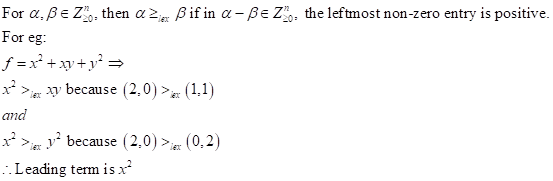

- Graded lexicographic ordering:

               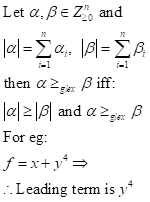

Multi-variate Polynomial Division:

- Dividing 2 polynomials:

              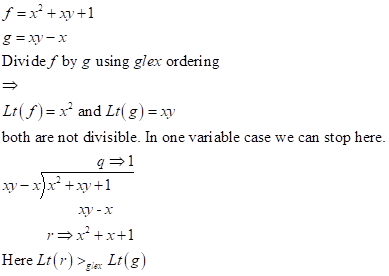

clear all;clc
syms x y
f = x^2+x*y+1;
d = x*y-x;
[r,q] = polynomialReduce(f,d)

$$r = x^{2}+x+1$$

$$q = 1$$

- Dividing by a system of polynomials: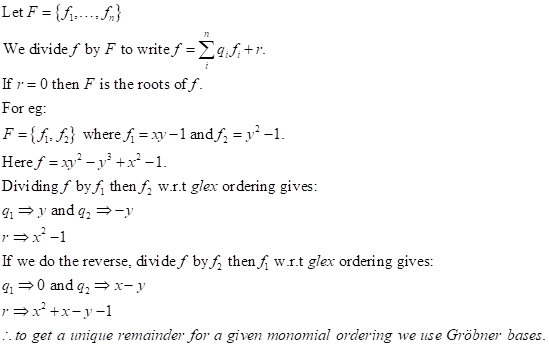

syms x y
f = x*y^2-y^3+x^2-1;
d1 = [x*y - 1, y^2 - 1];
d2 = [y^2 - 1, x*y - 1];
[r1,q1] = polynomialReduce(f,d1) %#ok<*ASGLU> 

$$r1 = x^{2}-1$$

$$q1 = \left(\begin{array}{cc} y & -y \end{array}\right)$$

[r2,q2] = polynomialReduce(f,d2)

$$r2 = x^{2}+x-y-1$$

$$q2 = \left(\begin{array}{cc} x-y & 0 \end{array}\right)$$

Rings: A ring is a non-empty set equipped with 2 operations that satisfy the following axioms:

- It is closed under addition: $if \ a \in R \ and \ b \in R \ then \ a+b \in R$

- Associative

- Commutative

- Should have additive identity: $i.e \ 0_R \in a \ such\ that\ a+0_R=a=0_R+a \  \forall a \in R$

- Should have additive inverse.

- Closed under multiplication:$if\ a \in R\ and\ b\in R\ then\ a\bullet b \in R$

- Distributive and assosiative.

- *A set of ****Z****, ****Q**** and ****C**** are rings. Set of even numbers form a ring but set of odd nos don’t.*

Field:

- A subring *I* of a ring *R* is an **ideal** *iff *when* r **∈** R *and*a **∈ I, *then* r.a **∈** I *and *a.r **∈ I*. For eg. a set of even integers is an ideal of the ring ***Z*** and $\{0_R\}$ and ***R*** are ideals for every ring ***R***.

             

- The zero ideal is generated by a single element set; *I=<0**R**>={0**R**} **∀*ring ***R***.

- Ideals can have different set of generators.

- Noetherian Rings: A ring ***R*** is a Noetherian ring if every ideal *I* of ***R*** is finitely generated. And, according to Hilbert’s Basis Theorem if *R* is a Noetherian ring then so is the polynomial ring *R[x]*.

Gröbner Basis: (LM(*f*) denotes fixed monomial ordering and LT(*f*) denotes the leading term.)

- A Gröbner basis of an ideal *I* is a set of generators of *I*.

- For a fixed monomial ordering a finite subset *G=*$\{g_1,...,g_t\}$ of an ideal *I* is said to be a Gröbner basis if:$<LT(g_1),...,LT(g_t)>=<LT(I)>$

- Reduced Gröbner basis: A RGb for a set of polynomials *F* is a Gröbner basis *G*of *F* such that: 1. LC is 1 $\forall p \in G$ and for all $p \in G$, none of the terms of *p* is divisible by the $LT(q) \ \forall \ q \in G-\{p\}$

- S-polynomials: 

             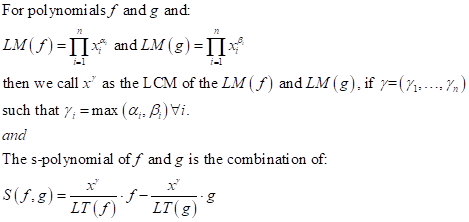

- For example:

             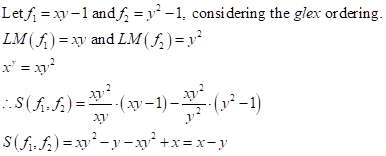

Buchberger's Algorithm:

- Chose the monomial ordering.

- Start with *G := F*.

- Repeat G’ := G until G = G’

              For example:

             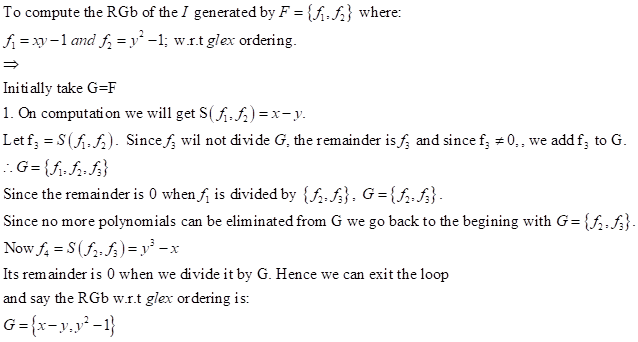

syms x y
r = [x*y-1, y^2-1];
G = gbasis(r)

$$G = \left(\begin{array}{cc} y^{2}-1 & x-y \end{array}\right)$$

Unique Remainders:

- For example:

            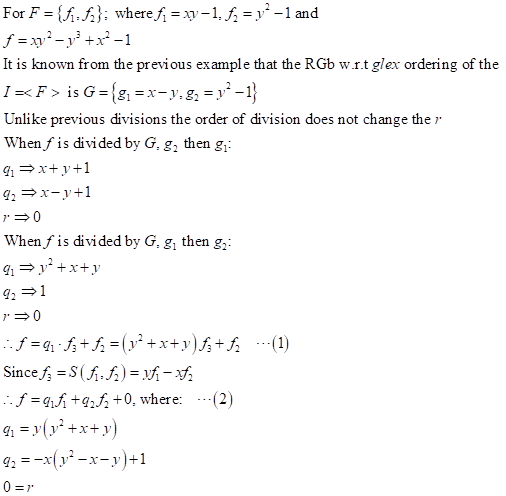

syms x y
f = x*y^2-y^3+x^2-1;
d = [x*y-1,y^2-1];
G = gbasis(d);
Gd = [G(1,2) G(1,1)];
[r1,q1] = polynomialReduce(f,G)

$$r1 = 0$$

$$q1 = \left(\begin{array}{cc} x-y+1 & x+y+1 \end{array}\right)$$

[r2,q2] = polynomialReduce(f,Gd)

$$r2 = 0$$

$$q2 = \left(\begin{array}{cc} y^{2}+y+x & 1 \end{array}\right)$$

        A zero remainder implies that the solutions of *F* are the roots of *f*. In conclusion, to divide a polynomial *f* by                  a set of polynomials *F* to get a unique remainder the following steps are to be followed:

- Compute Gröbner basis $G=\{g_1,...,g_t\}$ of the ideal *I=<F>.*

- Divide *f* by *G *to get a unique remainder *r*.

- Trace the quotients$q_i,\ i=1\ to\ n$ from the S-polynomials to write $f=q_1f_1+...+q_nf_n+r$

#### Inverse Kinematics Example

        Consider a robot with 2 revolute joints. 

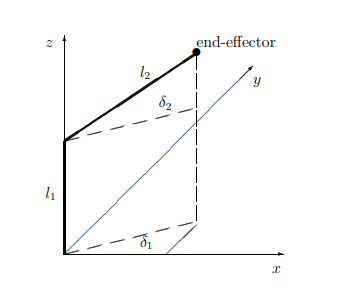

here we have 9 parameters; $l_1,l_2,p_x,p_y,p_z,\delta_1,\delta_2,s_1,s_2,c_1,c_2$ where $l_1,l_2$ are the link lengths; $p_x,p_y,p_z$ are the end-effector x-, y- and z- coordinates; $\delta_1, \delta_2$ are the angles describing the revolutions of the revolute joints; and $s_1,s_2,c_1,c_2$ are the sines and cosines of $\delta_1 \ and \ \delta_2$. 

        So with these we consider a system of equations:

given $l_1,l_2,p_x,p_z,$

solve for $s_1,s_2,c_1,c_2,p_y$

syms l1 l2 px pz s1 s2 c1 c2 py

Using these we can get 5 equations:


$$l_2.c_1.c_2-p_x=0,\\
l_2.s_1.c_2-p_y=0,\\
l_2.s_2 + l_1-p_z=0,\\
c_{1}^{2}+s_{1}^{2}-1=0\\
c_{2}^{2}+s_{2}^{2}-1=0$$


F = [l2*c1*c2 - px, l2*s1*c2-py, l2*s2+l1-pz, c1^2+s1^2-1, c2^2+s2^2-1];
G = gbasis(F,[c1 c2 s1 s2 py],'MonomialOrder','lexicographic');
siz = size(G);
for i=1:siz(2)
    disp(G(i))
end

$$c_{1}+\frac{\mathrm{px}\,\mathrm{py}\,s_{1}}{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}$$

$$c_{2}+\frac{\mathrm{py}\,s_{1}\,\left(-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}\right)}{l_{2}\,\left({l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}\right)}$$

$$\frac{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}{-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}}+{s_{1}}^{2}$$

$$s_{2}+\frac{l_{1}-\mathrm{pz}}{l_{2}}$$

$${l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}$$

These can be transformed into a Grobner Basis in the polynomial ring $\mathbb{Q}(l_1,l_2,p_x,p_z)[c_1,c_2,s_1,s_2,p_y]$:

This gives us 5 equations and 5 unknowns and thus solves the problem. Let:


$$l_1=30\\ l_2=45\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30$$


L1 = 30;L2 = 45; PX = 45*sqrt(6)/4; PZ = 45*sqrt(2)/2+30;

subs1 = subs(G(5), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol1 = solve(subs1 , py,'ReturnConditions',true);
disp('py=')

py=


disp(vpa(sol1.py,6))

$$\left(\begin{array}{c} -15.9099\\ 15.9099 \end{array}\right)$$

PY = vpa(sol1.py(2),6);

Here we get py=$\left(\begin{array}{c}
-15.9099\\
15.9099
\end{array}\right)$. We take py=15.9099

subs2 = subs(G(4), [l1, l2, pz], [L1, L2, PZ]);
sol2 = solve(subs2 , s2,'ReturnConditions',true);
disp('s2=')

s2=


disp(vpa(sol2.s2,6))

$$0.707107$$

s2=$0.707107$

subs3 = subs(G(3), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol3 = solve(subs3 , s1,'ReturnConditions',true);
disp('s1=')

s1=


disp(vpa(sol3.s1,6))

$$\left(\begin{array}{c} -0.5\\ 0.5 \end{array}\right)$$

S1 = vpa(sol3.s1(2),6);

s1=$\left(\begin{array}{c}
-0.5\\
0.5
\end{array}\right)$. We take s1=0.5

subs4 = subs(G(2), [s1, l1, l2, px, py, pz], [S1, L1, L2, PX, PY, PZ]);
sol4 = solve(subs4 , c2,'ReturnConditions',true);
disp('c2=')

c2=


disp(vpa(sol4.c2,6))

$$0.707107$$

c2=$0.707107$

subs5 = subs(G(1), [s1, l1, l2, px, py, pz], [S1, L1, L2, PX, PY, PZ]);
sol5 = solve(subs5 , c1,'ReturnConditions',true);
disp('c1=')

c1=


disp(vpa(sol5.c1,6))

$$0.866025$$

and c1=$0.866025$

Thus the problem is solved with:


$$l_1=30;l_2=45,\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30\\
and\ the\ solved\ variables\ are:\\
p_y=15.9099\\
s_2=0.707107\\
s_1=0.5\\
c_2=0.707107\\
c_1=0.866025$$
